clear all;

# Exercice 5

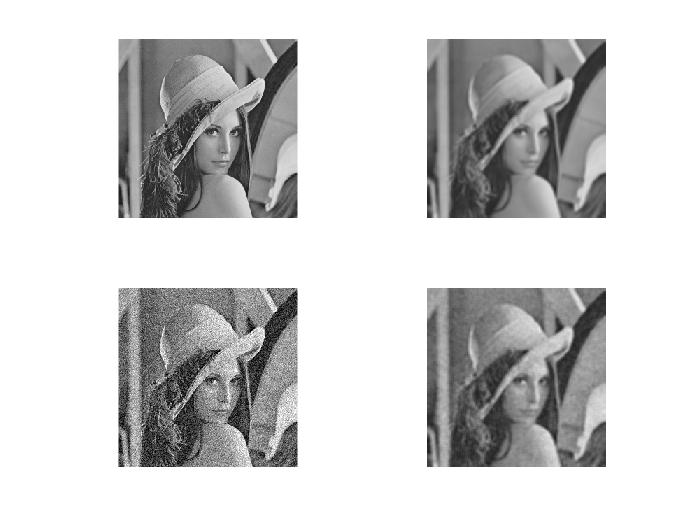

M = [1/25 1/25 1/25 1/25 1/25; 1/25 1/25 1/25 1/25 1/25; 1/25 1/25 1/25 1/25 1/25; 1/25 1/25 1/25 1/25 1/25; 1/25 1/25 1/25 1/25 1/25];
%I = imread("lena-soderberg-topless.jpg");
I = imread("lena.tif");
%I = imread("trump.jpg");

%Traitement des images
ILisse = AppliquerMasque(I, M);
IBruit = imnoise(I);
IBruitLisse = AppliquerMasque(IBruit, M);

%Affichage en bloc de 2x2
figure
subplot(2, 2, 1);
imshow(I);
subplot(2, 2, 2);
imshow(uint8(ILisse));
subplot(2, 2, 3);
imshow(uint8(IBruit));
subplot(2, 2, 4);
imshow(uint8(IBruitLisse));

### Question 3

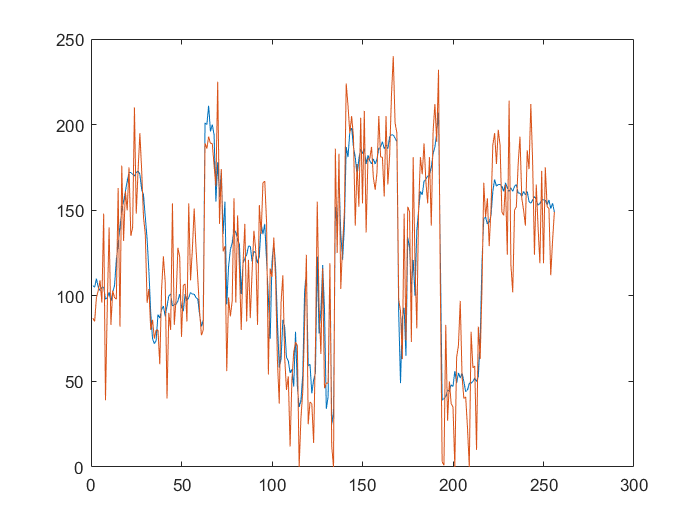

%Affichage d'un profil de ligne
figure
plot(I(100,:))
hold on
plot(IBruit(100, :))

# Exercice 6

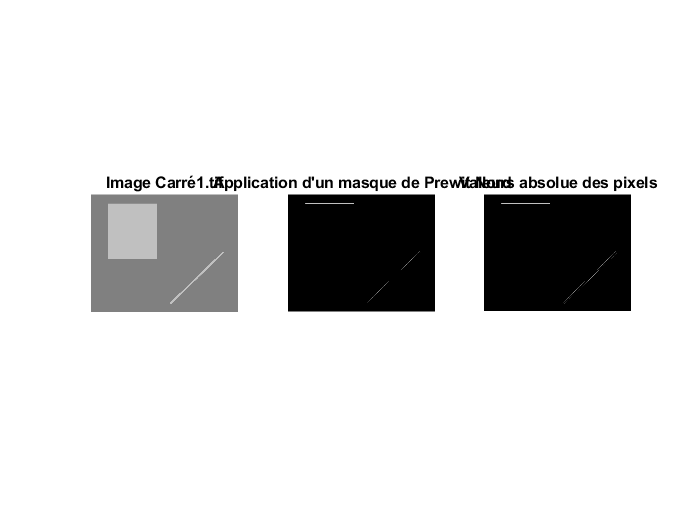

%Definition des masques de Prewit
MPrewitNord = [1 1 1 ; 0 0 0 ; -1 -1 -1]; 
MPrewitEst = [-1 0 1 ; -1 0 1 ; -1 0 1];

ICarre = imread("Carré1.tif");

ICarreP1 = AppliquerMasque(ICarre, MPrewitNord);
ICarreP2 = AppliquerMasque(ICarre, MPrewitEst);

%Affichage
figure
subplot(1, 3, 1);
imshow(ICarre);
title("Image Carré1.tif");
subplot(1, 3, 2);
imshow(uint8(ICarreP1));
title("Application d'un masque de Prewit Nord");
subplot(1, 3, 3);
imshow(uint8(abs(ICarreP1)));
title("Valeurs absolue des pixels");

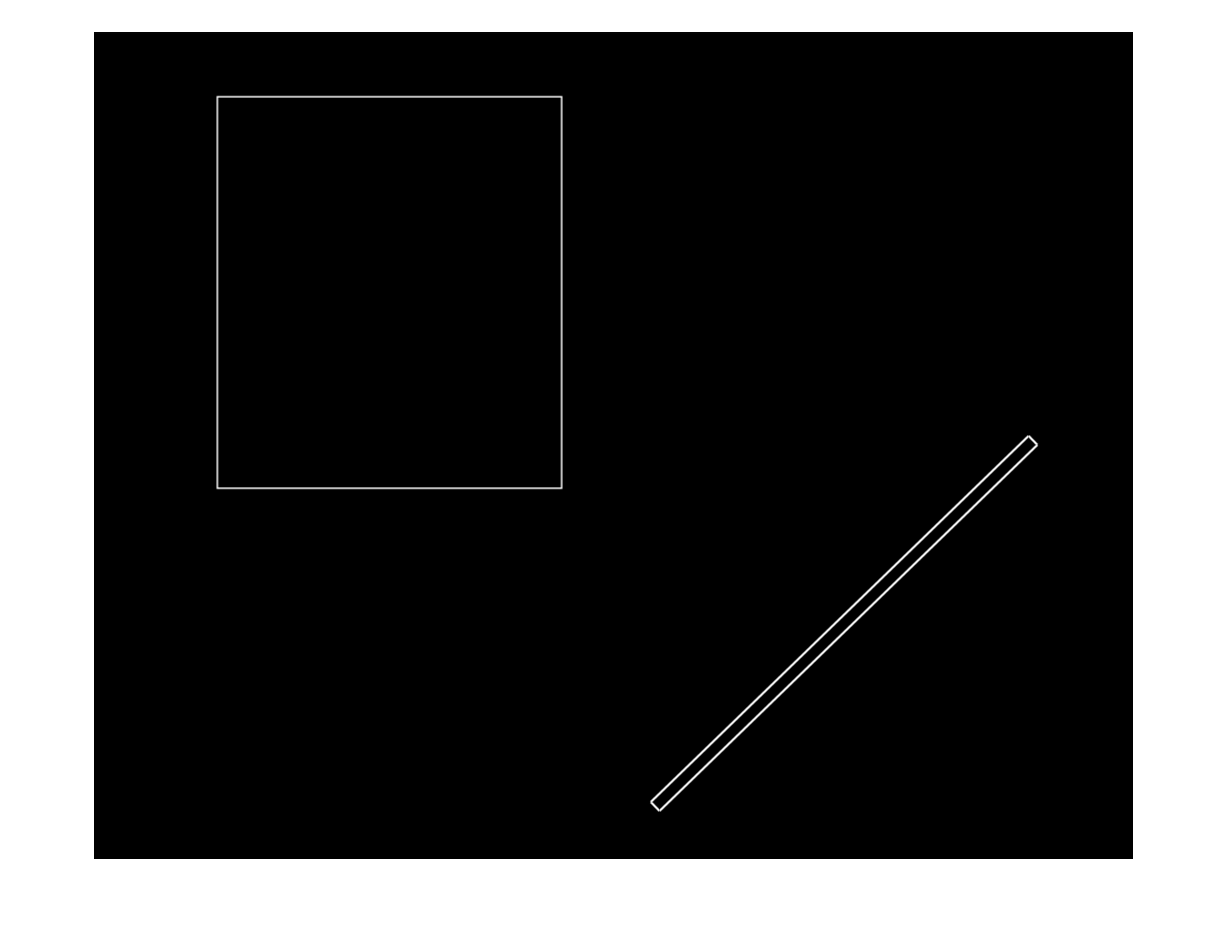


%Argument
ICarreP3 = abs(ICarreP1) + abs(ICarreP2);
figure
imshow(uint8(ICarreP3));

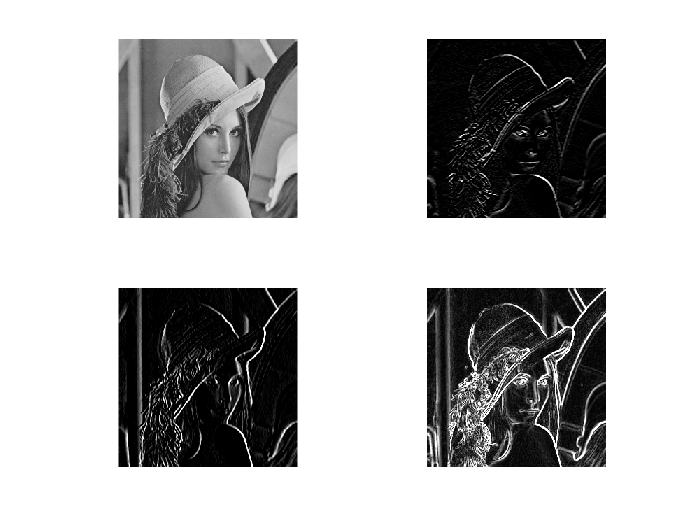


%Pour l'image Lena
LenaContourN = AppliquerMasque(I, MPrewitNord);
LenaContourE = AppliquerMasque(I, MPrewitEst);
LenaContourT = abs(LenaContourE) + abs(LenaContourN);

%Affichage
figure
subplot(2, 2, 1);
imshow(I);
subplot(2, 2, 2);
imshow(uint8(LenaContourN));
subplot(2, 2, 3);
imshow(uint8(LenaContourE));
subplot(2, 2, 4);
imshow(uint8(LenaContourT));

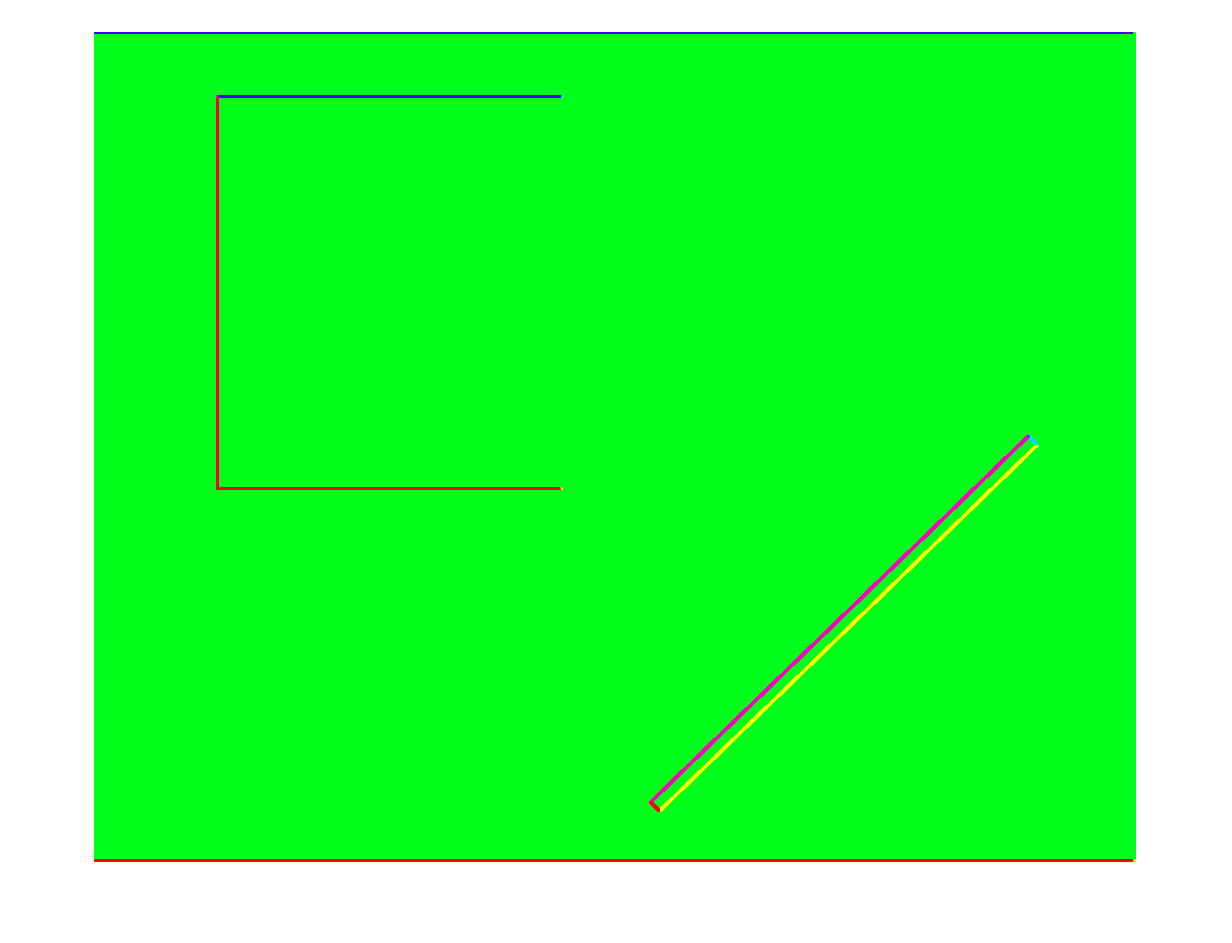


%Visualisation en fausse couleur
Arg = atan2d(ICarreP1, ICarreP2);
figure; imshow(uint8(Arg+90), hsv); %+90 pour avoir des valeurs positives

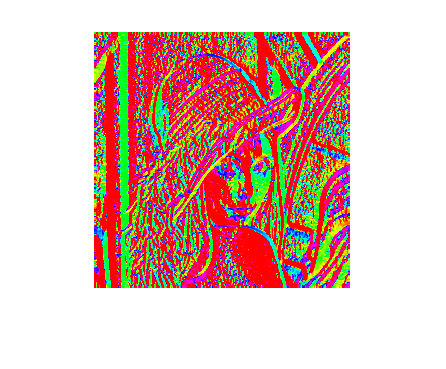

Arg_Lena = atan2d(LenaContourN, LenaContourE);
figure; imshow(uint8(Arg_Lena+90),hsv);

# Exercice 7

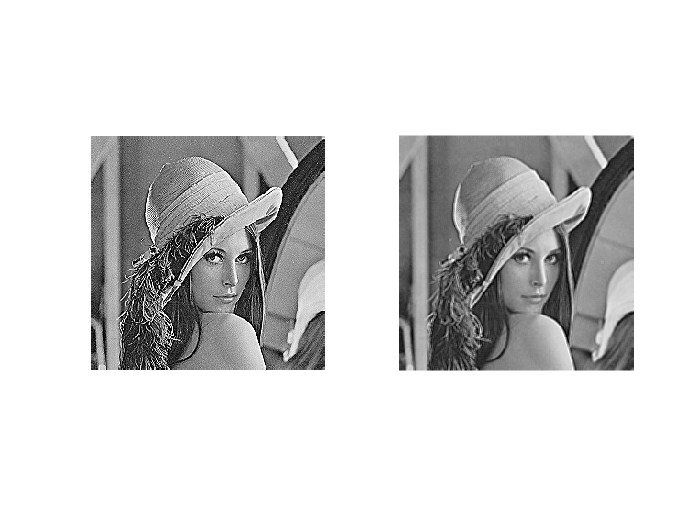

%Définition du Masque de réhaussement contraste
MRc = [0 -1 0; -1 5 -1; 0 -1 0];
M3 = [1/9 1/9 1/9; 1/9 1/9 1/9; 1/9 1/9 1/9];

IRc = AppliquerMasque(I, MRc);
IRcF = AppliquerMasque(IRc, M3);

%Affichage
figure
subplot(1, 2, 1);
imshow(uint8(IRc));
subplot(1, 2, 2);
imshow(uint8(IRcF));

### Fonction pour appliquer un masque à une image

function R = AppliquerMasque(I, M)

R = double(I);
I = double(I);
[nbC, nbL] = size(I);
[taille1, taille2] = size(M);

%On vérifie que la matrice est une matrice carrée
if taille1 ~= taille2 
    error("La matrice n'est pas une matrice carrée");
else
    taille = taille1;
end

%On vérifie que la matrice est de taille impaire
if mod(taille, 2) == 0
    error("La matrice n'est pas de taille impaire")
end

%On vérifie que le filtre est applicable à l'image
if nbC < taille
    error("L'image n'est pas assez large pour appliquer le filtre")
end
if nbL < taille
    error("L'image n'est pas assez haute pour appliquer le filtre")
end

decal = (taille - 1 )/2;
Mres = retournerMasque(M);

%Application du filtre
for i = (1+decal):(nbC-decal)
    for j = (1+decal):(nbL-decal) 
        
        %On initialise les positions dans le masque
        imat = 1;
        sum = 0;
        %On parcourt les voisins du pixel courant
        for posi = i-decal:i+decal
            jmat = 1;
            for posj = j-decal:j+decal
                sum = sum + Mres(imat, jmat) * I(posi, posj);
                jmat = jmat+1;
            end
            imat = imat+1;
        end
        R(i, j) = sum;
    end
end

%Recopie des bords
%haut et bas
for i = 1:decal
    R(:,i) = R(:,i+decal);
    R(:,nbL+1-i) = R(:,nbL+1-i-decal);
end
%droite et gauche
for j = 1:decal
    R(j,:) = R(j+decal, :);
    R(nbC+1-j, :) = R(nbC+1-j-decal, :);
end

%R = uint8(R);
return;

end


### Fonctionnement de retournement de masque

function Mres = retournerMasque(M)

Mres = M;
[taille1, taille2] = size(M);

%On vérifie que la matrice est une matrice carrée
if taille1 ~= taille2 
    error("La matrice n'est pas une matrice carrée");
else
    taille = taille1;
end

for i = 1:taille
    for j = 1:taille
        Mres(i,j) = M(taille+1-i, taille+1-j);
    end
end

return

end